Problema 1

%{
clear
A=[0 0 1];
B=[6 0 1]; 
C=[3 4 1];
S=[2 0 0; 0 3 0; 0 0 1];
p11=A*S;
p21=B*S;
p31=C*S;

R=[cosd(30) sind(30) 0; -sind(30) cosd(30) 0; 0 0 1];
p12=p11*R;
p22=p21*R;
p32=p31*R;

S2=[1 0 0; 0 2 0; 0 0 1];
p13=p12*S2;
p23=p22*S2;
p33=p32*S2;

triplot(delaunay([A(1),B(1),C(1)],[A(2),B(2),C(2)]),[A(1),B(1),C(1)],[A(2),B(2),C(2)], 'Color', 'b')
hold on
triplot(delaunay([p12(1),p22(1),p32(1)],[p12(2),p22(2),p32(2)]),[p12(1),p22(1),p32(1)],[p12(2),p22(2),p32(2)], 'Color', 'r')
hold off
%}

Problema 2

%{
clear
A=[0 0 1];
B=[3 0 1];
C=[3 3 1];
D=[0 3 1];
T=[1 0 0; 0 1 0; 1 2 1];
p11=A*T;
p21=B*T;
p31=C*T;
p41=D*T;

S=[1 0 0; 0 2 0; 0 0 1];
p12=p11*S;
p22=p21*S;
p32=p31*S;
p42=p41*S;

R=[cosd(40) sind(40) 0; -sind(40) cosd(40) 0; 0 0 1];
p13=p12*R;
p23=p22*R;
p33=p32*R;
p43=p42*R;

%invertidas
p14=p11*R;
p24=p21*R;
p34=p31*R;
p44=p41*R;

p15=p14*S;
p25=p24*S;
p35=p34*S;
p45=p44*S;

%Graficacion
line([A(1),B(1)],[A(2),B(2)], 'Color', 'r')
line([B(1),C(1)],[B(2),C(2)], 'Color', 'r')
line([C(1),D(1)],[C(2),D(2)], 'Color', 'r')
line([D(1),A(1)],[D(2),A(2)], 'Color', 'r')
hold on
line([p13(1),p23(1)],[p13(2),p23(2)], 'Color', 'g')
line([p23(1),p33(1)],[p23(2),p33(2)], 'Color', 'g')
line([p33(1),p43(1)],[p33(2),p43(2)], 'Color', 'g')
line([p43(1),p13(1)],[p43(2),p13(2)], 'Color', 'g')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
line([p15(1),p25(1)],[p15(2),p25(2)], 'Color', 'b')
line([p25(1),p35(1)],[p25(2),p35(2)], 'Color', 'b')
line([p35(1),p45(1)],[p35(2),p45(2)], 'Color', 'b')
line([p45(1),p15(1)],[p45(2),p15(2)], 'Color', 'b')
hold off
%}

Problema 3

%{
A=[-4 -3 1];
B=[4 -3 1];
C=[4 3 1];
D=[-4 3 1];

R=[cosd(30) sind(30) 0; -sind(30) cosd(30) 0; 0 0 1];
p11=A*R;
p21=B*R;
p31=C*R;
p41=D*R;

T=[1 0 0; 0 1 0; -3 -4 1];
p12=p11*T;
p22=p21*T;
p32=p31*T;
p42=p41*T;

S=[2 0 0; 0 3 0; 0 0 1];
p13=p12*S;
p23=p22*S;
p33=p32*S;
p43=p42*S;
%inversion
p14=p11*S;
p24=p21*S;
p34=p31*S;
p44=p41*S;

p15=p14*T;
p25=p24*T;
p35=p34*T;
p45=p44*T;

%Graficacion
line([A(1),B(1)],[A(2),B(2)], 'Color', 'r')
line([B(1),C(1)],[B(2),C(2)], 'Color', 'r')
line([C(1),D(1)],[C(2),D(2)], 'Color', 'r')
line([D(1),A(1)],[D(2),A(2)], 'Color', 'r')
hold on
line([p13(1),p23(1)],[p13(2),p23(2)], 'Color', 'g')
line([p23(1),p33(1)],[p23(2),p33(2)], 'Color', 'g')
line([p33(1),p43(1)],[p33(2),p43(2)], 'Color', 'g')
line([p43(1),p13(1)],[p43(2),p13(2)], 'Color', 'g')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
line([p15(1),p25(1)],[p15(2),p25(2)], 'Color', 'b')
line([p25(1),p35(1)],[p25(2),p35(2)], 'Color', 'b')
line([p35(1),p45(1)],[p35(2),p45(2)], 'Color', 'b')
line([p45(1),p15(1)],[p45(2),p15(2)], 'Color', 'b')
hold off
%}

Problema 4

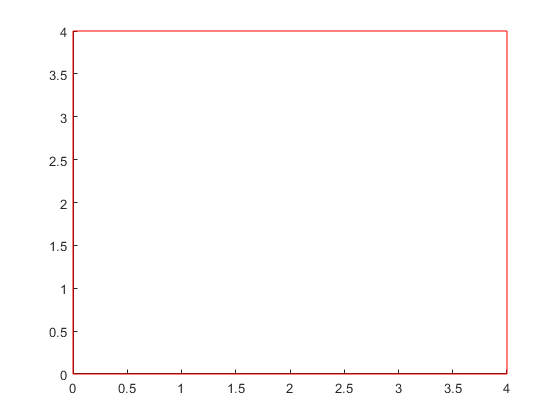

A=[0 0 0 1];
B=[4 0 0 1];
C=[4 4 0 1];
D=[0 4 0 1];
E=[0 0 4 1];
F=[4 0 4 1];
G=[4 4 4 1];
H=[0 4 4 1];

%Graficacion
line([A(1),B(1)],[A(2),B(2)],[A(3),B(3)], 'Color', 'r')
line([B(1),C(1)],[B(2),C(2)],[B(3),C(3)], 'Color', 'r')
line([C(1),D(1)],[C(2),D(2)],[C(3),D(3)], 'Color', 'r')
line([D(1),A(1)],[D(2),A(2)],[D(3),A(3)], 'Color', 'r')
line([E(1),F(1)],[E(2),F(2)],[E(3),F(3)], 'Color', 'r')
line([F(1),G(1)],[F(2),G(2)],[F(3),G(3)], 'Color', 'r')
line([G(1),H(1)],[G(2),H(2)],[G(3),H(3)], 'Color', 'r')
line([H(1),E(1)],[H(2),E(2)],[H(3),E(3)], 'Color', 'r')
line([E(1),A(1)],[E(2),A(2)],[E(3),A(3)], 'Color', 'r')
line([F(1),B(1)],[F(2),B(2)],[F(3),B(3)], 'Color', 'r')
line([G(1),C(1)],[G(2),C(2)],[G(3),C(3)], 'Color', 'r')
line([H(1),D(1)],[H(2),D(2)],[H(3),D(3)], 'Color', 'r')